# Comparison of forward bias data taken in different days

In 2022-06-17 and 2022-06-28 I took cwEDMR spectra in forward bias of pin SC in Elexsys. Here I compare the data that were taken in these two days, to chose the set of measurements that will be analyzed further (fit and bootstrap).

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder1 = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210617';
cw17 = load([Opt.LFolder1, '\cwEDMR_2021_06_17.mat']);
Opt.LFolder2 = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210628';
cw28 = load([Opt.LFolder2, '\cwEDMR_2021_06_28.mat']);

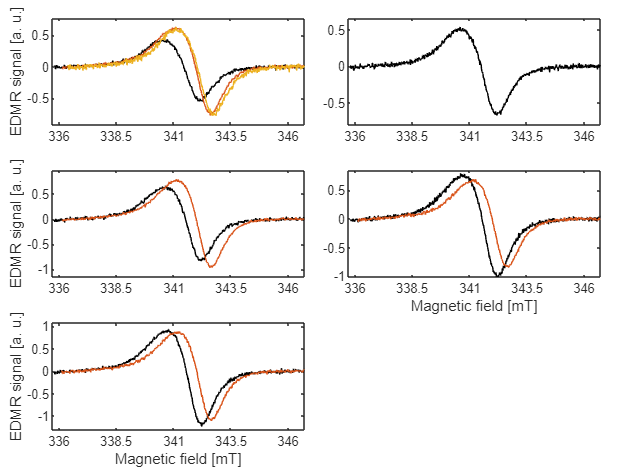

% ID (V): 1.1, 1.15, 1.2, 1.25, 1.3
subplotID = ["(a)", "(b)", "(c)", "(d)", "(e)"]; 
figure()
tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact')
LineW = 0.8;
nexttile
plot(cw17.x(:, 1), cw17.y(:, 1), 'Color', [0 0 0])
hold on
plot(cw28.x(:, 1), cw28.y(:, 1))
plot(cw17.x(:, 1) + 0.1763 - 0.089 + 0.5, scaleY(cw17.y(:, 1), cw28.y(:, 1)))
xlim([335.7 346.7]); ylim(setAxLim(cw28.y(:, 1), 0.1));
xticks(336:2.5:346); yticks(-1:0.5:1);
ylabel('EDMR signal [a. u.]', 'FontSize', 10)
nexttile
plot(cw17.x(:, 2), cw17.y(:, 2), 'Color', [0 0 0])
xticks(336:2.5:346); yticks(-1:0.5:1);
xlim([335.7 346.7]); ylim(setAxLim(cw17.y(:, 2), 0.1));
for icw = 2:4
    nexttile()
    x17 = cw17.x(:, icw + 1); y17 = cw17.y(:, icw + 1);
    x28 = cw28.x(:, icw); y28 = cw28.y(:, icw);
    plot(x17, y17, 'Color', [0 0 0])
    hold on
    plot(x28, y28)
    
    xticks(336:2.5:346); yticks(-1:0.5:1);
    xlim([335.7 346.7]); ylim(setAxLim(y28, 0.1));

    if icw == 2 || icw == 4
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end
end